time = 1:240;
plot(time,Lemon)

函数或变量 'Lemon' 无法识别。

[xData, yData] = prepareCurveData( time, Lemon );
ft = fittype( 'fourier8' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.0657236956817948];
[fitresult, gof] = fit( xData, yData, ft, opts );
figure( 'Name', 'fourier8' );
h = plot( fitresult, xData, yData );
legend( h, 'Lemon vs. time', 'fourier8', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'Lemon', 'Interpreter', 'none' );
grid on
y_fit = feval(fitresult, xData);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\datelemon.txt', y_fit, 'delimiter', '\t', 'precision', 6);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\lemon.txt', Lemon, 'delimiter', '\t', 'precision', 6);

%% When data has processed, employ the next preprocessing of the series
load("X:\05_Data\pythonProject\DTW-LSTM\result\processedTrainDataset.mat")
trainPercent = 5/6;
TrainLimit = 200;
delta = 40;
data = Processed;
for i = 1 : delta
    data(i + TrainLimit) = Lemon(i + TrainLimit);
end

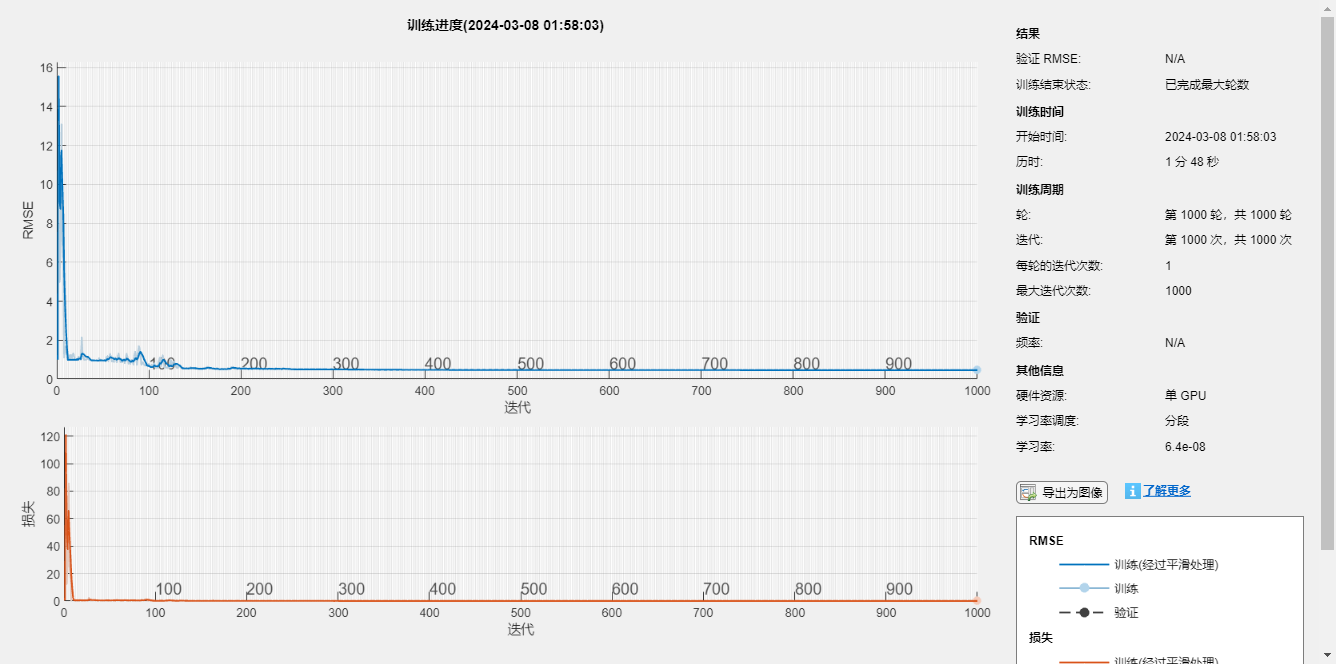

%% LSTM Process
YPred = 0;
numTimeStepsTrain = floor(trainPercent*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*15;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
net = trainNetwork(XTrain,YTrain,layers,options);

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 1.9140e+03

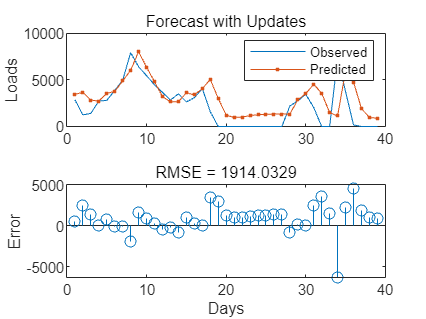

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Loads")
title("Forecast with Updates")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

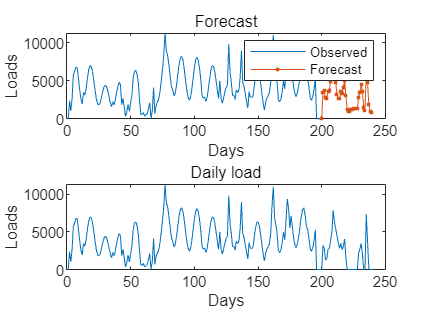

figure
subplot(2,1,1)
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Days")
ylabel("Loads")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Days")
ylabel("Loads")
title("Daily load")

%% Alignment of the last errors may require manual action
for i = 1 : delta
    YReal(i) = data(i + TrainLimit);
end
YPred(delta) = YPred(delta - 1);


errors = YPred - YReal;
MAE = mean(abs(errors))

MAE = 992.9225

SSE = sum(errors.^2)

SSE = 4.6163e+07

RMSE = sqrt(mean(errors.^2))

RMSE = 1.0743e+03

MAPE = mean(abs(errors) ./ max(abs(YReal), eps)) * 100

MAPE = 4.0648e+04